## Elbow Plot Trials

M = 1000;           % declare number of iterations
alpha = 1;
numK = 25;          % how many k values to loop through
increment = 5;      % how far apart should the k values be spaced?
kErrors = zeros(numK);

% replace "weightData" with the name of your similarity matrix
for i=1:numK
    disp(i);
    [newH,errors] = multUp_SymNMF(weightData,i*increment,alpha,M); 
    kErrors(i) = errors(end);
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25



## Plotting the Elbow

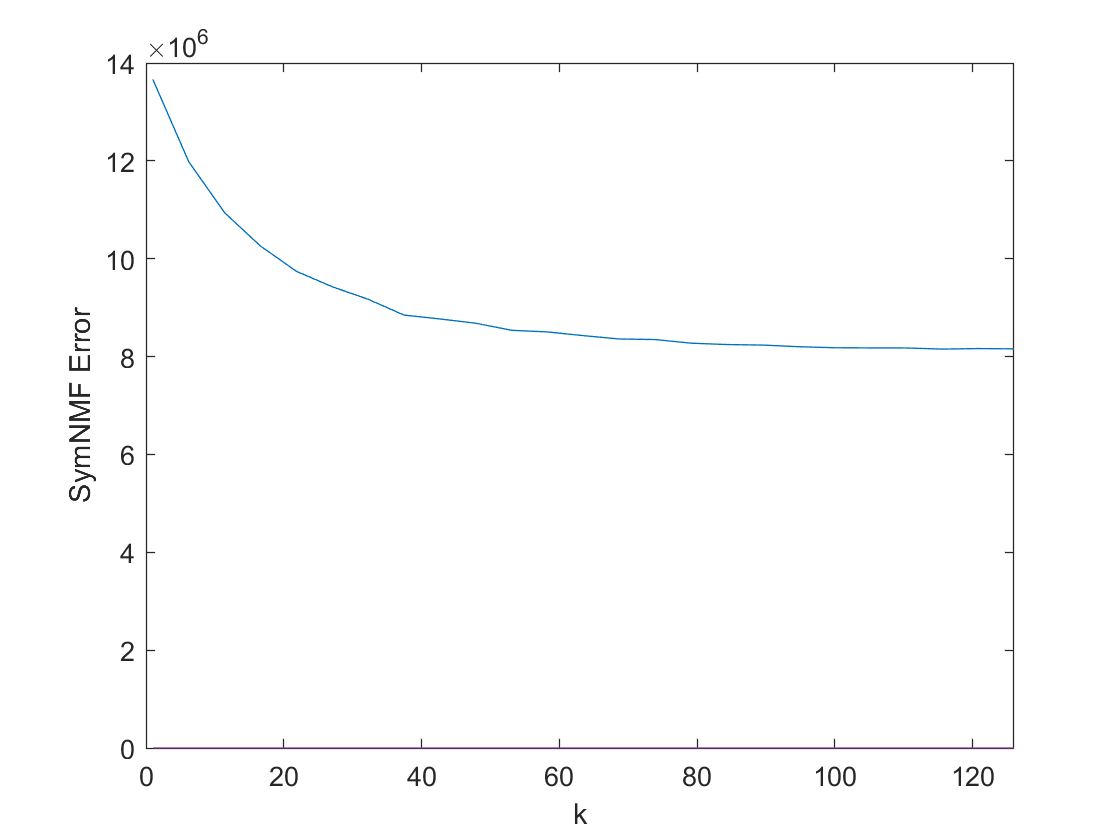

plot(linspace(1,numK*increment+1,numK),kErrors);
ylabel('SymNMF Error');
xlabel('k');
xlim([0 numK*increment+1])